clear all;

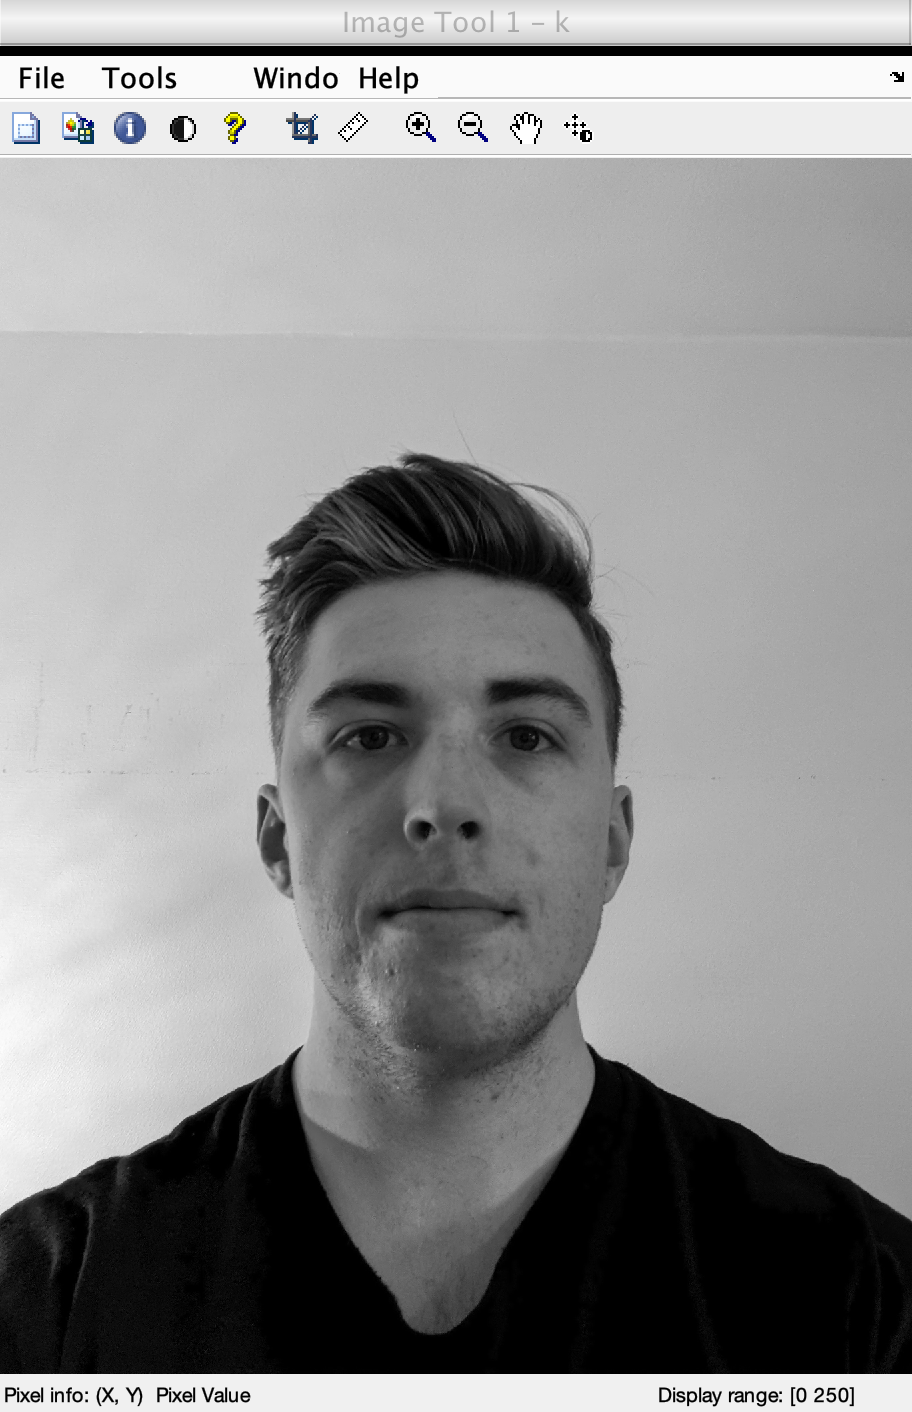

% MATLAB code for Scharr operator edge detection
k=imread("me.jpg");
%k=imread("city.jpg");

k=rgb2gray(k);
k1=double(k);

s_msk=[-3 0 3; -10 0 10; -3 0 3];
kx=conv2(k1, s_msk, 'same');
ky=conv2(k1, s_msk', 'same');
ked=sqrt(kx.^2 + ky.^2);

%display the images.
imtool(k,[]);

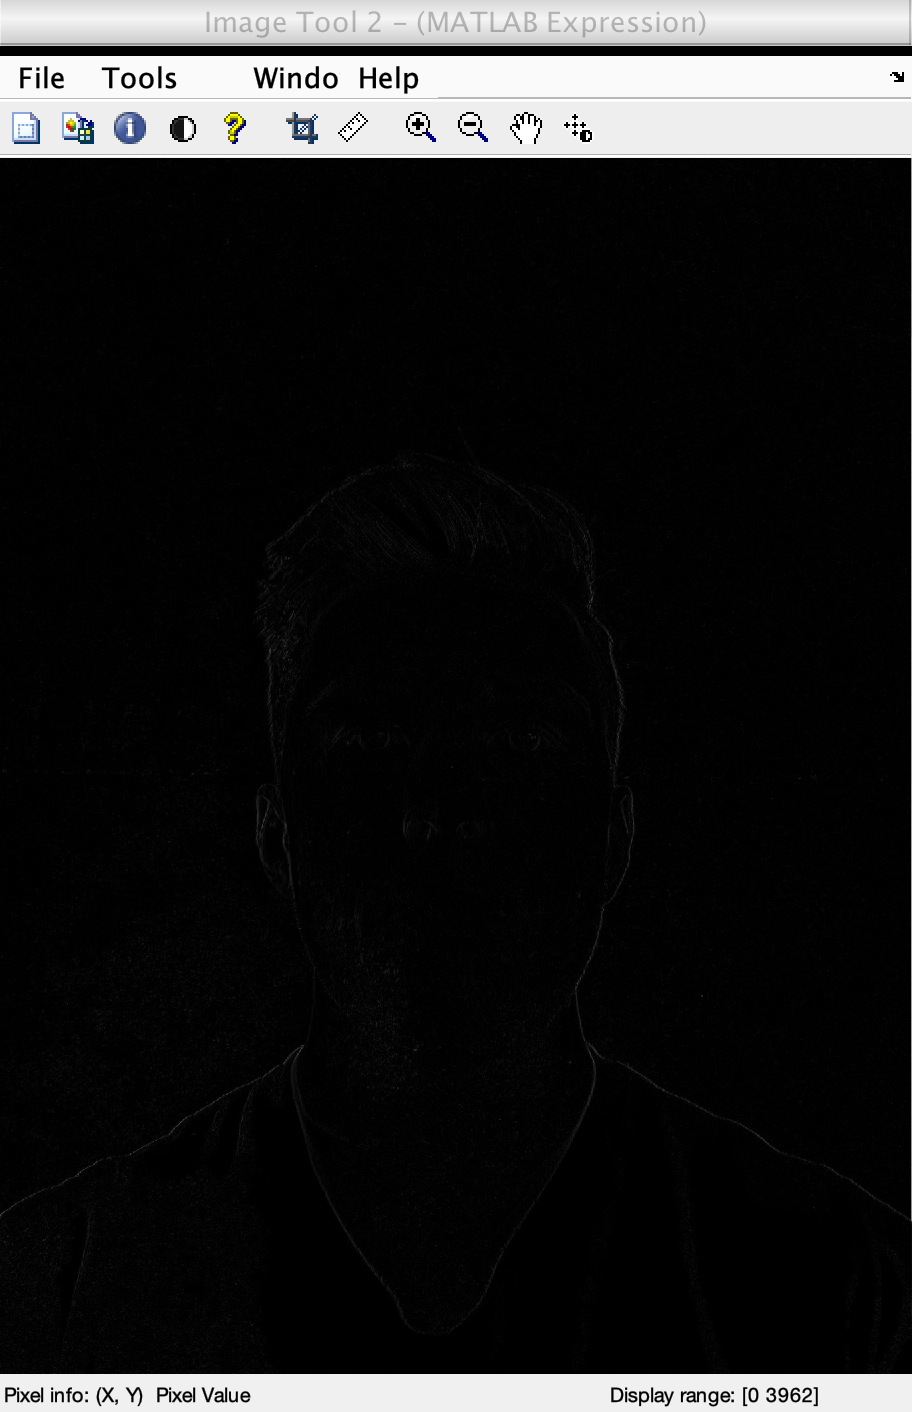

%display the edge detection along x-axis.
imtool(abs(kx), []);

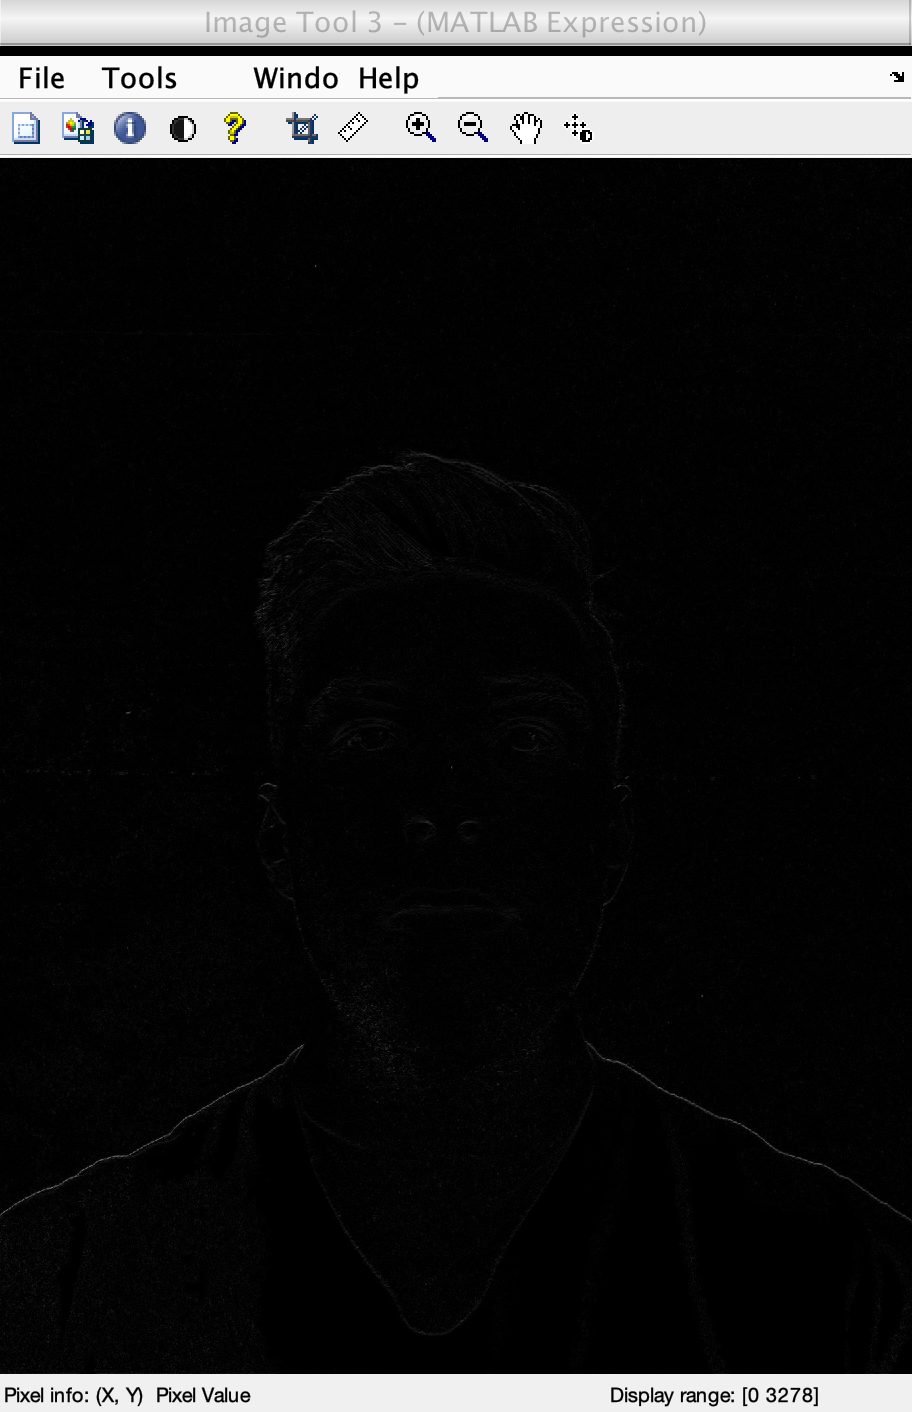

%display the edge detection along y-axis.
imtool(abs(ky),[]);

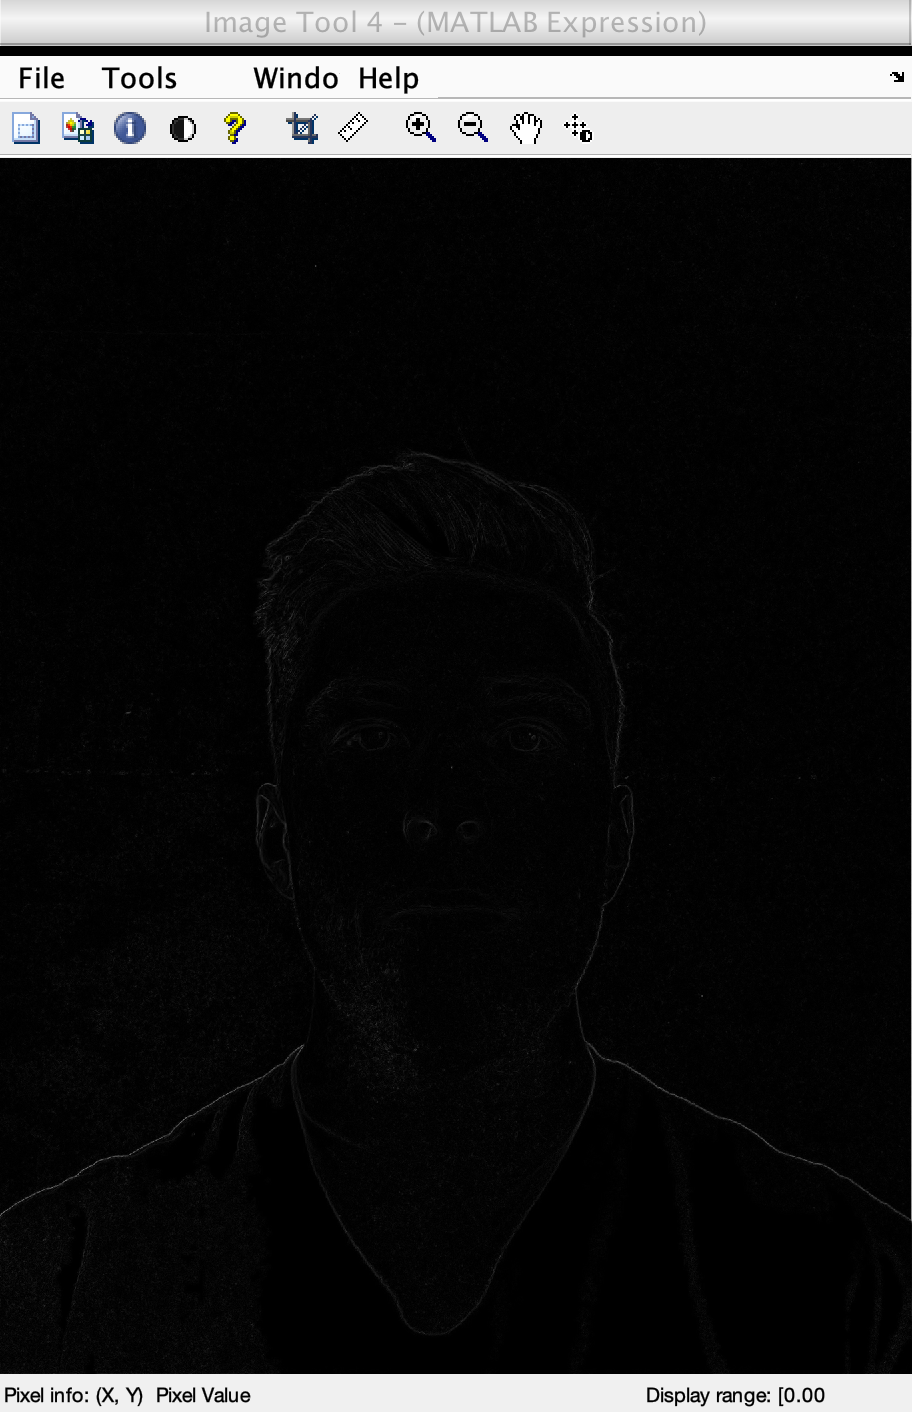

%display the full edge detection.
imtool(abs(ked),[]);